clear
clc

cd ..\'mat data'\
load('Colorchecker_original_RGBValue.mat')
load('reflectance.mat')
cd ..\'code'\

sequence = [4 8 12 16 20 24 3 7 11 15 19 23 2 6 10 14 18 22 1 5 9 13 17 21]

seqence =      4     8    12    16    20    24     3     7    11    15    19    23     2     6    10    14    18    22     1     5     9    13    17    21


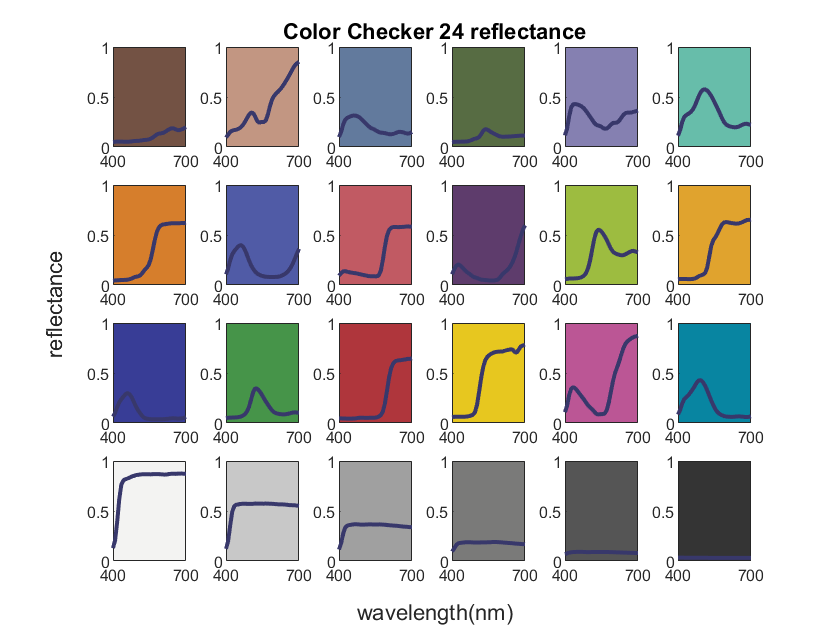

fig = figure;
for i = 1:24 %color checker
    x = 400:(700-400)/35:700;
    subplot(4,6,i)
    plot(x,reflectance(i,:),'Color',[0.219,0.219,0.419],'LineWidth',2)
    xlim([400 700])
    ylim([0 1])
    xticks([400 700])
    set(gcf,"visible","on")
    set(gca,'color',[R(sequence(i)) G(sequence(i)) B(sequence(i))])

end
han=axes(fig,'visible','off'); 
han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
title(han,'Color Checker 24 reflectance');
xlabel(han,'wavelength(nm)');
ylabel(han,'reflectance');